# **Newton's 2nd Law model:**   3-dof Spring Mass Damper system

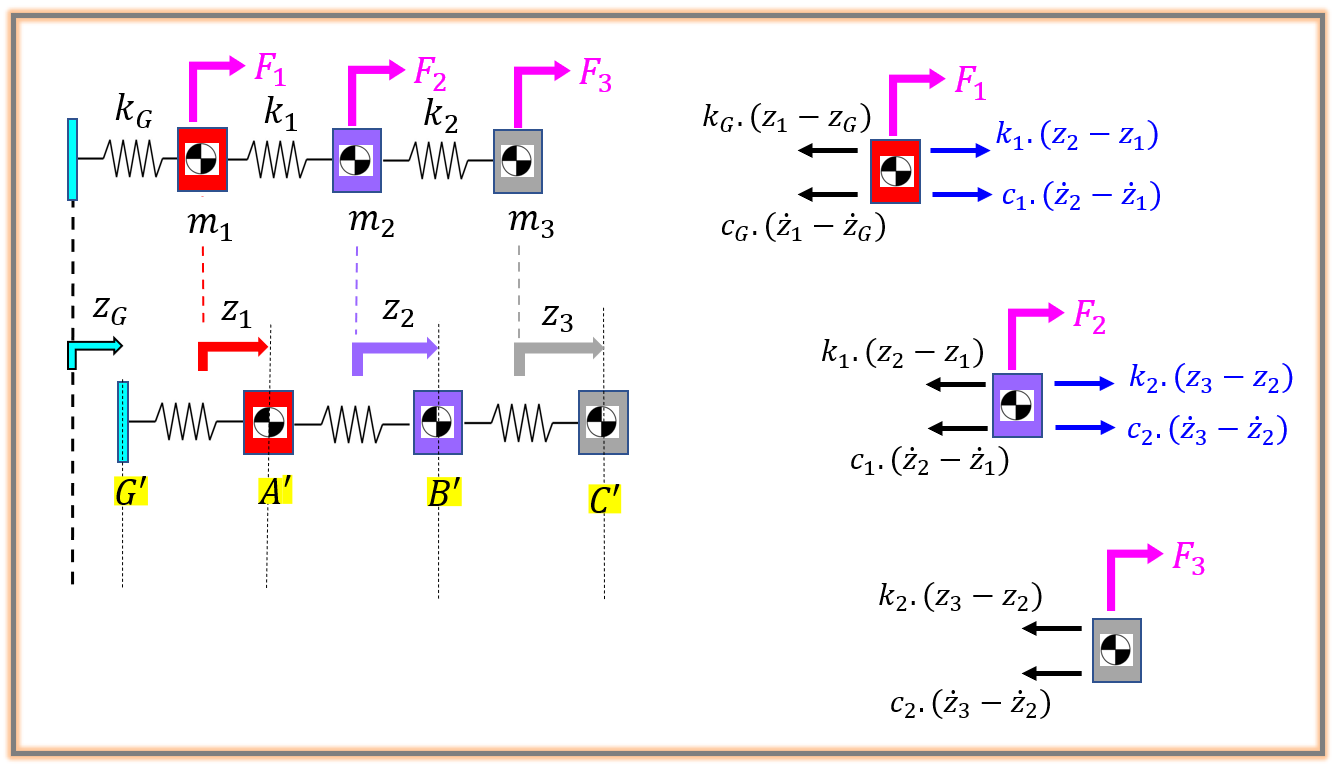

Newton's 2nd Law:   $m\ldotp a=\sum F_i$

- 
$$m\ldotp {\ddot{z} }_1 \;\;=\;F_1 \;-\;k_G \ldotp \left(z_1 -z_G \right)\;\;-\;\;c_G \ldotp \left({\dot{z} }_1 -{\dot{z} }_G \right)\;\;\;+\;\;\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;+\;\;c_1 \ldotp \left({\dot{z} }_2 -{\dot{z} }_1 \right)$$


- 
$$m\ldotp {\ddot{z} }_2 \;\;=\;F_2 \;-\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;\;\;-\;\;c_1 \ldotp \left({\dot{z} }_2 -{\dot{z} }_1 \right)\;\;\;\;+\;\;\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;+\;\;c_2 \ldotp \left({\dot{z} }_3 -{\dot{z} }_2 \right)$$


- 
$$m\ldotp {\ddot{z} }_3 \;\;=\;F_3 \;-\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;\;\;-\;\;c_2 \ldotp \left({\dot{z} }_3 -{\dot{z} }_2 \right)\;\;\;\;$$


Which rearranging gives us:

- 
$$m\ldotp {\ddot{z} }_1 \;\;+\;k_G \ldotp \left(z_1 -z_G \right)\;\;+\;c_G \ldotp \left({\dot{z} }_1 -{\dot{z} }_G \right)\;\;\;-\;\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;-\;c_1 \ldotp \left({\dot{z} }_2 -{\dot{z} }_1 \right)=F_1$$


- 
$$m\ldotp {\ddot{z} }_2 \;\;+\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;\;\;+\;c_1 \ldotp \left({\dot{z} }_2 -{\dot{z} }_1 \right)\;\;\;\;-\;\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;-\;c_2 \ldotp \left({\dot{z} }_3 -{\dot{z} }_2 \right)=F_2$$


- 
$$m\ldotp {\ddot{z} }_3 \;+\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;\;\;+\;c_2 \ldotp \left({\dot{z} }_3 -{\dot{z} }_2 \right)=F_3$$


Which in Matrix form is:

- 
$$\left\lbrack \begin{array}{ccc}
m_1  & \bullet  & \bullet \\
\bullet  & m_2  & \bullet \\
\bullet  & \bullet  & m_3 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
{\ddot{z} }_1 \\
{\ddot{z} }_2 \\
{\ddot{z} }_3 
\end{array}\right\rbrack \;\;+\left\lbrack \begin{array}{ccc}
\left(c_G +c_1 \right) & \left(-c_1 \right) & \bullet \\
\left(-c_1 \right) & \left(c_1 +c_2 \right) & \left(-c_2 \right)\\
\bullet  & \left(-c_2 \right) & \left(c_2 \right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
{\dot{z} }_1 \\
{\dot{z} }_2 \\
{\dot{z} }_3 
\end{array}\right\rbrack \;\;+\;\;\left\lbrack \begin{array}{ccc}
\left(k_G +k_1 \right) & \left(-k_1 \right) & \bullet \\
\left(-k_1 \right) & \left(k_1 +k_2 \right) & \left(-k_2 \right)\\
\bullet  & \left(-k_2 \right) & \left(k_2 \right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
z_1 \\
z_2 \\
z_3 
\end{array}\right\rbrack \;\;=\;\;\left\lbrack \begin{array}{c}
F_1 \;+\;k_G \ldotp z_{G\;} \;+\;c_G \ldotp {\dot{z} }_G \\
F_2 \\
F_3 
\end{array}\right\rbrack$$


Which has the classic shape:

- 
$$M\ldotp \ddot{Z} \;\;+\;C\ldotp \dot{Z} \;\;+\;K\ldotp Z\;\;=F$$



function z_dot_dot = bh_newton_smd_3dof_ODE(m1,m2,m3,  cg,c1,c2,  kg,k1,k2, Fext_col, z_col, z_dot_col, zg, zg_dot);

    z_dot_dot = zeros(3,1);

    [M, C, K] = bh_newton_smd_3dof_model_MCK(m1,m2,m3, kg,k1,k2, 'DAMPING_C', [cg,c1,c2] );

    F_tot = Fext_col(:)  +  [(kg*zg + cg*zg_dot);0;0];

Now solve the problem:

- 
$$M\ldotp \ddot{Z} \;\;=F-C\ldotp \dot{Z} \;\;-K\ldotp Z$$


- 
$$A\ldotp x\;\;\;\;=b$$


    A = M;
    b = F_tot - C*z_dot_col(:) - K*z_col(:);
    
    z_dot_dot = A \ b;
end